% This code was generated via ChatGPT 5.4 ("extended thinking").


## F-16A Level 1 Sizing Analysis — Class-Based Example

% This live script performs a Level 1 sizing pass for the F-16A example using
% the toolkit classes supplied with the project.
%
% Main objects used:
%   * AircraftDesign
%   * GeometryLevel1
%   * AeroLevel1
%   * PropulsionLevel1
%   * WeightLevel1
%   * MissionAnalysisLevel1
%   * ConstraintAnalysisClass
%   * Requirements
%   * SizingClassLevel1
%
% The script assumes the corresponding class files, import utilities, design
% workbook, requirements table, constraints table, and mission profile are on
% the MATLAB path.

clear;

%% Project setup
% Set this to the folder containing your classes, import utilities, design
% spreadsheet/workbook, requirements file, constraints file, and mission data.
projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";


## Create the aircraft design object

% AircraftDesign is the project-level object. It imports the design geometry,
% fuselage data, propulsion data, weight data, general aircraft data, and
% requirements reference.

design = AircraftDesign( ...
     designName, ...
     RequirementsName = requirementsName, ...
     ConstraintsName  = constraintsName, ...
     AutoLoad         = true);


% Keep the constraints filename explicit in case the design constructor was
% given a blank or nonstandard value.
if strlength(string(design.constraints_filename)) == 0
     design.constraints_filename = constraintsName;
end

disp("AircraftDesign object created:")

AircraftDesign object created:


disp(design)

  AircraftDesign with properties:

                     Name: "F-16A Block 50"
                     geom: [1×1 struct]
                  general: [1×1 struct]
               propulsion: [1×1 struct]
          propulsion_type: "low bpr turbofan"
                n_engines: []
                 CivOrMil: []
                     role: []
                  weights: [1×1 struct]
                     type: "Jet fighter"
              wing_config: []
              tail_config: []
            fuselage_type: []
               nose_shape: []
             requirements: [1×1 struct]
    requirements_filename: []
     constraints_filename: "Constraints"
            WeightResults: []
              AeroResults: []
        PropulsionResults: []
           internalvolume: []


## Build the Level 1 analysis objects

% These objects are intentionally lower-fidelity than the Level 3 versions.
% They rely on historical estimates, tabulated assumptions, and simple mission
% weight fractions/Breguet-style estimates.


% Compute required constraints
% constraint_obj.constraint_analysis;

## Weight

weight_obj       = F16WeightLevel1(design);

## Geometry

geometry_obj     = F16GeometryLevel1(design, weight_obj);

## Aerodynamics object

Initialize some things for the Aero object

aero_obj         = F16AeroLevel1("jet fighter", geometry_obj, weight_obj);
aero_obj.Cf = AeroLevel1.get_Cf("air force fighter", 1);
aero_obj.CL_minD = 0.02843; % Hardcoded from Brandt

% Get CL_max_TO
aero_obj.CL_max_TO = aero_obj.get_CLmax_values("fighter", "takeoff", "mean");

% Get CL_max_land
aero_obj.CL_max_Land = aero_obj.get_CLmax_values("fighter", "landing", "mean");

% Get CL_max_clean
aero_obj.CL_max_clean = aero_obj.get_CLmax_values("fighter", "clean", "mean");

## Propulsion

propulsion_obj   = F16PropulsionLevel1(design);

## Mission

mission_obj      = F16MissionAnalysisLevel1(missionName);

## Constraints

Build the constraints.

constraint_obj   = F16ConstraintAnalysis();
% Need to update the aerodynamic constraints for each given constraint
% (altitude, mach number)

% Get table of state vectors (mach number, altitude) for each constraint
% (constraint name)
constraints_table = Import_Constraints(constraintsName);

constraints_length = length(constraints_table.Altitude_ft_)

constraints_length = 8


% Load up miscellaneous constraints
beta = constraints_table.W_Wto;
n = constraints_table.n;
mu = constraints_table.SurfaceFrictionCoefficient_mu_;
Ps = constraints_table.PS_ft_s_;
distance = constraints_table.Distance_ft_;

% Clean up inputs before things get messy
Ps(isnan(Ps)==1)=0;
n(isnan(n)==1)=0;
distance(isnan(distance)==1)=0;
mu(isnan(mu)==1)=0;


% Get the Mach number and altitude
M = constraints_table.MachNumber;
h_alt = constraints_table.Altitude_ft_;
state_vector = [M, h_alt];

% Set up geometry stuff
AR = geometry_obj.mainwings.AR;
LE_sweep_deg = geometry_obj.mainwings.LE_sweep;
Cf = aero_obj.Cf; % Compute this
S_wet = geometry_obj.get_design_S_wet("jet fighter", weight_obj.W_TO_guess);
S_ref = geometry_obj.mainwings.S_ref;
e_osw = aero_obj.e_osw;
T_SL_dry = propulsion_obj.T_SL_dry;
T_SL_wet = propulsion_obj.T_SL_wet;
gamma = 1.4;

W_S = constraint_obj.Wto_S_range;

% Get density at sea level
[T, a, P, rho_SL] = atmosisa(0);

% Convert rho_SL to slugs
rho_SL = rho_SL*0.00194032033; % Convert from kg/m^3 -> imperial units

for i=1:constraints_length
     current_constraint = constraints_table.Row{i}
     AB_percent = constraints_table.AB_(i);

     M = state_vector(i,1);
     h_alt = state_vector(i,2);
     newstatevector = [M, h_alt];

     % Get density at current altitude
     [T, a, P, rho] = atmosisa(h_alt*0.3048);

     % Convert rho to slugs
     rho = rho*0.00194032033; % Convert from kg/m^3 -> imperial units

     % Convert a to ft/s
     a = a*3.2808399;

     if isnan(AB_percent)==true
          AB_percent = 1.0;
     elseif (AB_percent > 1.0)
          AB_percent = AB_percent/100;
     elseif (0.0 < AB_percent < 1.0)
          % Do nothing
     else
          error("Error handler.") % Just in case something weird happens.
     end

     % This thing breaks for "takeoff" and "landing" segments.
     % Need takeoff/landing velocity for computations (CD0, alpha,
     % alpha_dry/wet). To get that velocity, I need the weight. To get the
     % weight, I need the velocity... I can start with the guess weight.
     if (current_constraint == "Takeoff")
          % Do takeoff calculations
          % V = 168; % Hardcoded takeoff velocity (ft/s)
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_TO, rho)
               V_TO = 1.2*V_stall;
               M_TO = V_TO./a;

               takeoff_statevector = [M_TO, h_alt];

               [K1, K2] = aero_obj.get_K(AR, e_osw, M_TO, LE_sweep_deg, aero_obj.CL_minD);
               [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints(takeoff_statevector, e_osw, Cf, S_wet, S_ref)

               [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(takeoff_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               aero_constraints_takeoff(k, :) = [e_osw, K1, K2, CD0, V_TO, q];
               thrust_constraints_takeoff(k, :) = [alpha, alpha_dry, alpha_wet];
          end
          e_osw_takeoff = aero_constraints_takeoff(:,1);
          K1_takeoff = aero_constraints_takeoff(:,2);
          K2_takeoff = aero_constraints_takeoff(:,3);
          CD0_takeoff = aero_constraints_takeoff(:,4);
          V_takeoff = aero_constraints_takeoff(:,5);
          q_takeoff = aero_constraints_takeoff(:,6);

          alpha_takeoff = thrust_constraints_takeoff(:,1);
          alpha_dry_takeoff = thrust_constraints_takeoff(:,2);
          alpha_wet_takeoff = thrust_constraints_takeoff(:,3);
     elseif (current_constraint == "Landing")
          % Do landing calculations
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_Land, rho)
               V_Land = 1.3*V_stall;
               M_Land = V_Land./a;

               landing_statevector = [M_Land, h_alt];

               [K1, K2] = aero_obj.get_K(AR, e_osw, M_Land, LE_sweep_deg, aero_obj.CL_minD);
               [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints(landing_statevector, e_osw, Cf, S_wet, S_ref)

               [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(landing_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               % thrust_constraints(i, :) = [0, 0, 0];
               % aero_constraints(i, :) = [0, 0, 0, 0, 0, 0];
               aero_constraints_landing(k, :) = [e_osw, K1, K2, CD0, V_Land, q];
               thrust_constraints_landing(k, :) = [alpha, alpha_dry, alpha_wet];
          end
          e_osw_landing = aero_constraints_landing(:,1);
          K1_landing = aero_constraints_landing(:,2);
          K2_landing = aero_constraints_landing(:,3);
          CD0_landing = aero_constraints_landing(:,4);
          V_land = aero_constraints_landing(:,5);
          q_land = aero_constraints_landing(:,6);

          alpha_landing = thrust_constraints_landing(:,1);
          alpha_dry_landing = thrust_constraints_landing(:,2);
          alpha_wet_landing = thrust_constraints_landing(:,3);
     else
          % Compute thrust constraints (alpha_dry, alpha_wet, alpha)
          [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(newstatevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

          % Compute thrust at altitude (sanity check)
          T_alt_wet = PropulsionUtils.thrust_from_lapse(alpha_wet, T_SL_wet)
          T_alt_dry = PropulsionUtils.thrust_from_lapse(alpha_dry, T_SL_dry)

          thrust_constraints(i, :) = [alpha, alpha_dry, alpha_wet];

          [K1, K2] = aero_obj.get_K(AR, e_osw, M, LE_sweep_deg, aero_obj.CL_minD)
          [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints([M, h_alt], e_osw, Cf, S_wet, S_ref)
          CD0 = aero_obj.get_CD0(Cf, S_wet, S_ref);
          e_osw = aero_obj.get_e_osw(AR, geometry_obj.mainwings.LE_sweep);
          aero_constraints(i, :) = [e_osw, K1, K2, CD0, V, q];
     end
end

current_constraint = 'Max Mach'

alpha = 0.5494

alpha_dry = 0.3089

alpha_wet = 0.5494

T_alt_wet = 1.3060e+04

T_alt_dry = 4.6332e+03

K1 = 0.2760

K2 = 0

e_osw = 0.9086

CD0 = 0.0270

V = 1.5496e+03

q = 850.6819

current_constraint = 'Cruise'

alpha = 0.1391

alpha_dry = 0.2204

alpha_wet = 0.3674

T_alt_wet = 8.7330e+03

T_alt_dry = 3.3066e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0270

V = 842.5695

q = 251.5161

current_constraint = 'Max Alt'

alpha = 0.1875

alpha_dry = 0.1125

alpha_wet = 0.1875

T_alt_wet = 4.4559e+03

T_alt_dry = 1.6871e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0270

V = 842.2259

q = 128.3319

current_constraint = 'Combat Subsonic'

alpha = 0.7526

alpha_dry = 0.4516

alpha_wet = 0.7526

T_alt_wet = 1.7890e+04

T_alt_dry = 6.7738e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0270

V = 902.0595

q = 515.2562

current_constraint = 'Combat Supersonic'

alpha = 0.6007

alpha_dry = 0.3546

alpha_wet = 0.6007

T_alt_wet = 1.4278e+04

T_alt_dry = 5.3187e+03

K1 = 0.2261

K2 = 0

e_osw = 0.9086

CD0 = 0.0270

V = 1.3559e+03

q = 651.3034

current_constraint = 'Excess Power'

alpha = 0.8608

alpha_dry = 0.5028

alpha_wet = 0.8608

T_alt_wet = 2.0462e+04

T_alt_dry = 7.5426e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0270

V = 937.3253

q = 771.0782

current_constraint = 'Takeoff'

V_stall = 99.4949

e_osw = 0.9086

CD0 = 0.0270

V = 119.3939

q = 16.9412

alpha = 1.0000

alpha_dry = 0.5996

alpha_wet = 1.0000

V_stall = 115.6026

e_osw = 0.9086

CD0 = 0.0270

V = 138.7231

q = 22.8706

alpha = 1.0000

alpha_dry = 0.5994

alpha_wet = 1.0000

V_stall = 129.7255

e_osw = 0.9086

CD0 = 0.0270

V = 155.6706

q = 28.8000

alpha = 0.9999

alpha_dry = 0.5993

alpha_wet = 0.9999

V_stall = 142.4550

e_osw = 0.9086

CD0 = 0.0270

V = 170.9460

q = 34.7294

alpha = 0.9999

alpha_dry = 0.5991

alpha_wet = 0.9999

V_stall = 154.1368

e_osw = 0.9086

CD0 = 0.0270

V = 184.9642

q = 40.6588

alpha = 0.9999

alpha_dry = 0.5989

alpha_wet = 0.9999

V_stall = 164.9936

e_osw = 0.9086

CD0 = 0.0270

V = 197.9923

q = 46.5882

alpha = 0.9998

alpha_dry = 0.5987

alpha_wet = 0.9998

V_stall = 175.1788

e_osw = 0.9086

CD0 = 0.0270

V = 210.2146

q = 52.5176

alpha = 0.9998

alpha_dry = 0.5986

alpha_wet = 0.9998

V_stall = 184.8036

e_osw = 0.9086

CD0 = 0.0270

V = 221.7643

q = 58.4471

alpha = 0.9997

alpha_dry = 0.5984

alpha_wet = 0.9997

V_stall = 193.9512

e_osw = 0.9086

CD0 = 0.0270

V = 232.7415

q = 64.3765

alpha = 0.9997

alpha_dry = 0.5982

alpha_wet = 0.9997

V_stall = 202.6865

e_osw = 0.9086

CD0 = 0.0270

V = 243.2238

q = 70.3059

alpha = 0.9996

alpha_dry = 0.5980

alpha_wet = 0.9996

V_stall = 211.0605

e_osw = 0.9086

CD0 = 0.0270

V = 253.2726

q = 76.2353

alpha = 0.9995

alpha_dry = 0.5978

alpha_wet = 0.9995

V_stall = 219.1148

e_osw = 0.9086

CD0 = 0.0270

V = 262.9377

q = 82.1647

alpha = 0.9995

alpha_dry = 0.5976

alpha_wet = 0.9995

V_stall = 226.8833

e_osw = 0.9086

CD0 = 0.0270

V = 272.2599

q = 88.0941

alpha = 0.9994

alpha_dry = 0.5974

alpha_wet = 0.9994

V_stall = 234.3944

e_osw = 0.9086

CD0 = 0.0270

V = 281.2733

q = 94.0235

alpha = 0.9993

alpha_dry = 0.5972

alpha_wet = 0.9993

V_stall = 241.6722

e_osw = 0.9086

CD0 = 0.0270

V = 290.0067

q = 99.9529

alpha = 0.9992

alpha_dry = 0.5970

alpha_wet = 0.9992

V_stall = 248.7372

e_osw = 0.9086

CD0 = 0.0270

V = 298.4847

q = 105.8824

alpha = 0.9991

alpha_dry = 0.5968

alpha_wet = 0.9991

V_stall = 255.6070

e_osw = 0.9086

CD0 = 0.0270

V = 306.7284

q = 111.8118

alpha = 0.9990

alpha_dry = 0.5966

alpha_wet = 0.9990

V_stall = 262.2969

e_osw = 0.9086

CD0 = 0.0270

V = 314.7563

q = 117.7412

alpha = 0.9989

alpha_dry = 0.5963

alpha_wet = 0.9989

V_stall = 268.8204

e_osw = 0.9086

CD0 = 0.0270

V = 322.5845

q = 123.6706

alpha = 0.9988

alpha_dry = 0.5961

alpha_wet = 0.9988

V_stall = 275.1893

e_osw = 0.9086

CD0 = 0.0270

V = 330.2271

q = 129.6000

alpha = 0.9986

alpha_dry = 0.5959

alpha_wet = 0.9986

V_stall = 281.4140

e_osw = 0.9086

CD0 = 0.0270

V = 337.6969

q = 135.5294

alpha = 0.9985

alpha_dry = 0.5957

alpha_wet = 0.9985

current_constraint = 'Landing'

V_stall = 89.5191

e_osw = 0.9086

CD0 = 0.0270

V = 116.3748

q = 16.0952

alpha = 1.0000

alpha_dry = 0.5996

alpha_wet = 1.0000

V_stall = 104.0118

e_osw = 0.9086

CD0 = 0.0270

V = 135.2153

q = 21.7286

alpha = 1.0000

alpha_dry = 0.5994

alpha_wet = 1.0000

V_stall = 116.7186

e_osw = 0.9086

CD0 = 0.0270

V = 151.7342

q = 27.3619

alpha = 0.9999

alpha_dry = 0.5993

alpha_wet = 0.9999

V_stall = 128.1718

e_osw = 0.9086

CD0 = 0.0270

V = 166.6234

q = 32.9952

alpha = 0.9999

alpha_dry = 0.5991

alpha_wet = 0.9999

V_stall = 138.6824

e_osw = 0.9086

CD0 = 0.0270

V = 180.2871

q = 38.6286

alpha = 0.9999

alpha_dry = 0.5990

alpha_wet = 0.9999

V_stall = 148.4506

e_osw = 0.9086

CD0 = 0.0270

V = 192.9858

q = 44.2619

alpha = 0.9998

alpha_dry = 0.5988

alpha_wet = 0.9998

V_stall = 157.6146

e_osw = 0.9086

CD0 = 0.0270

V = 204.8990

q = 49.8952

alpha = 0.9998

alpha_dry = 0.5986

alpha_wet = 0.9998

V_stall = 166.2743

e_osw = 0.9086

CD0 = 0.0270

V = 216.1566

q = 55.5286

alpha = 0.9998

alpha_dry = 0.5985

alpha_wet = 0.9998

V_stall = 174.5048

e_osw = 0.9086

CD0 = 0.0270

V = 226.8562

q = 61.1619

alpha = 0.9997

alpha_dry = 0.5983

alpha_wet = 0.9997

V_stall = 182.3642

e_osw = 0.9086

CD0 = 0.0270

V = 237.0735

q = 66.7952

alpha = 0.9996

alpha_dry = 0.5981

alpha_wet = 0.9996

V_stall = 189.8986

e_osw = 0.9086

CD0 = 0.0270

V = 246.8682

q = 72.4286

alpha = 0.9996

alpha_dry = 0.5979

alpha_wet = 0.9996

V_stall = 197.1453

e_osw = 0.9086

CD0 = 0.0270

V = 256.2889

q = 78.0619

alpha = 0.9995

alpha_dry = 0.5978

alpha_wet = 0.9995

V_stall = 204.1349

e_osw = 0.9086

CD0 = 0.0270

V = 265.3754

q = 83.6952

alpha = 0.9994

alpha_dry = 0.5976

alpha_wet = 0.9994

V_stall = 210.8930

e_osw = 0.9086

CD0 = 0.0270

V = 274.1608

q = 89.3286

alpha = 0.9994

alpha_dry = 0.5974

alpha_wet = 0.9994

V_stall = 217.4411

e_osw = 0.9086

CD0 = 0.0270

V = 282.6734

q = 94.9619

alpha = 0.9993

alpha_dry = 0.5972

alpha_wet = 0.9993

V_stall = 223.7977

e_osw = 0.9086

CD0 = 0.0270

V = 290.9370

q = 100.5952

alpha = 0.9992

alpha_dry = 0.5970

alpha_wet = 0.9992

V_stall = 229.9787

e_osw = 0.9086

CD0 = 0.0270

V = 298.9723

q = 106.2286

alpha = 0.9991

alpha_dry = 0.5968

alpha_wet = 0.9991

V_stall = 235.9978

e_osw = 0.9086

CD0 = 0.0270

V = 306.7972

q = 111.8619

alpha = 0.9990

alpha_dry = 0.5966

alpha_wet = 0.9990

V_stall = 241.8672

e_osw = 0.9086

CD0 = 0.0270

V = 314.4274

q = 117.4952

alpha = 0.9989

alpha_dry = 0.5964

alpha_wet = 0.9989

V_stall = 247.5975

e_osw = 0.9086

CD0 = 0.0270

V = 321.8768

q = 123.1286

alpha = 0.9988

alpha_dry = 0.5961

alpha_wet = 0.9988

V_stall = 253.1982

e_osw = 0.9086

CD0 = 0.0270

V = 329.1576

q = 128.7619

alpha = 0.9987

alpha_dry = 0.5959

alpha_wet = 0.9987


% Build tables for aero constraints
aero_constraints_table = array2table(aero_constraints, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

aero_constraints_table = 6×6 table
                          e_osw       K1           K2          CD0         V         q   
                         _______    _______    __________    ________    ______    ______
    Max Mach             0.90862    0.27603             0    0.026962    1549.6    850.68
    Cruise               0.90862    0.11677    -0.0066398    0.026962    842.57    251.52
    Max Alt              0.90862    0.11677    -0.0066398    0.026962    842.23    128.33
    Combat Subsonic      0.90862    0.11677    -0.0066398    0.026962    902.06    515.26
    Combat Supersonic    0.90862     0.2261             0    0.026962    1355.9     651.3
    Excess Power         0.90

e_osw = aero_constraints(:,1);
K1 = aero_constraints(:,2);
K2 = aero_constraints(:,3);
CD0 = aero_constraints(:,4);
V = aero_constraints(:,5);
q = aero_constraints(:,6);

% Build table for thrust constraints
thrust_constraints_table = array2table(thrust_constraints, "VariableNames",{'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

thrust_constraints_table = 6×3 table
                          alpha     alpha_dry    alpha_wet
                         _______    _________    _________
    Max Mach             0.54943     0.30888      0.54943 
    Cruise               0.13911     0.22044       0.3674 
    Max Alt              0.18746     0.11247      0.18746 
    Combat Subsonic      0.75265     0.45159      0.75265 
    Combat Supersonic    0.60067     0.35458      0.60067 
    Excess Power         0.86082     0.50284      0.86082 

alpha = thrust_constraints(:,1);
alpha_dry = thrust_constraints(:,2);
alpha_wet = thrust_constraints(:,3);

% Make all constraint arrays the same size as the imported arrays (beta, n,
% Ps, etc).


% Compute T/W and wing loading stuff for all constraints
TW_table = constraint_obj.createThrustLoadingTable(aero_constraints_table, beta, alpha, n, q, V, CD0, K1, Ps, W_S)

TW_table =     2.0968    1.5590    1.2440    1.0378    0.8926    0.7853    0.7029    0.6380    0.5856    0.5426    0.5069    0.4767    0.4511    0.4291    0.4102    0.3937    0.3793    0.3668    0.3557    0.3460    0.3374
    2.4915    1.8785    1.5256    1.2998    1.1453    1.0349    0.9538    0.8929    0.8467    0.8116    0.7848    0.7646    0.7497    0.7390    0.7319    0.7277    0.7259    0.7262    0.7283    0.7319    0.7369
    1.0015    0.7897    0.6765    0.6113    0.5731    0.5517    0.5413    0.5386    0.5415    0.5485    0.5587    0.5714    0.5861    0.6024    0.6200    0.6388    0.6584    0.6789    0.7000    0.7218    0.7440
    1.0216    0.8169    0.7107    0.6525    0.6214    0.6070    0.6037    0.6080    0.6180    0.6320    0.6493    0.6690    0.6908    0.7141    0.7388    0.7646    0.7913    0.8188    0.8470    0.8758    0.9050
    1.4801    1.1075    0.8910    0.7506    0.6531    0.5820    0.5284    0.4870    0.4543    0.4283    0.4073    0.3903    0.3765    0.3651    0



% Takeoff and landing analysis
% CALCULATIONS

T_Wto_takeoff = ConstraintAnalysisClass.takeoff_constraint(W_S, 1.2, beta(7), alpha_takeoff', rho, aero_obj.CL_max_TO, distance(7), CD0_takeoff(7), mu(7))

T_Wto_takeoff =     0.0965    0.1159    0.1353    0.1546    0.1740    0.1934    0.2128    0.2322    0.2516    0.2710    0.2904    0.3099    0.3293    0.3487    0.3681    0.3876    0.4070    0.4264    0.4459    0.4654    0.4848


Wto_S_Landing = ConstraintAnalysisClass.landing_constraint(distance(8), beta(8), rho, aero_obj.CL_max_Land, CD0_landing(8), mu(8))

Wto_S_Landing = 194.1046




% Package the aero and thrust results into a table format to use the
% pre-existing graph functions.
new_constraints_array = [aero_constraints, thrust_constraints];
new_constraints_table = array2table(new_constraints_array, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q', 'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

new_constraints_table = 6×9 table
                          e_osw       K1           K2          CD0         V         q        alpha     alpha_dry    alpha_wet
                         _______    _______    __________    ________    ______    ______    _______    _________    _________
    Max Mach             0.90862    0.27603             0    0.026962    1549.6    850.68    0.54943     0.30888      0.54943 
    Cruise               0.90862    0.11677    -0.0066398    0.026962    842.57    251.52    0.13911     0.22044       0.3674 
    Max Alt              0.90862    0.11677    -0.0066398    0.026962    842.23    128.33    0.18746 


% Trim takeoff and landing from constraints table
% constraints_table = [constraints_table, new_constraints_table]

% Get optimal wing loading and T/W
[constraint_obj.optimal_WS, constraint_obj.min_TW] = constraint_obj.solveOptimalPoint(TW_table, T_Wto_takeoff, W_S)

constraint_obj =   F16ConstraintAnalysis with properties:

           Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
              TW_table: []
         T_Wto_takeoff: []
            optimal_WS: 125
                min_TW: 0.7685
               Landing: []
         Wto_S_landing: []
                 T0_W0: []
              W0_S_ref: []
        T_Wto_required: [2.4915 1.8785 1.5256 1.2998 1.1453 1.0349 0.9559 0.9173 0.8861 0.8603 0.8387 0.8203 0.8045 0.7909 0.7790 0.7685 0.7913 0.8188 0.8470 0.8758 0.9050]
     constraints_table: []
    constraints_struct: []

constraint_obj =   F16ConstraintAnalysis with properties:

           Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
              TW_table: []
         T_Wto_takeoff: []
            optimal_WS: 125
                min_TW: 0.7685
               Landing: []
         Wto_S_landing: []
                 T0_W0: []
              W0_S_ref: []
        T_Wto_required: [2.4915 1.8785 1.5256 1.2998 1.1453 1.0349 0.9559 0.9173 0.8861 0.8603 0.8387 0.8203 0.8045 0.7909 0.7790 0.7685 0.7913 0.8188 0.8470 0.8758 0.9050]
     constraints_table: []
    constraints_struct: []

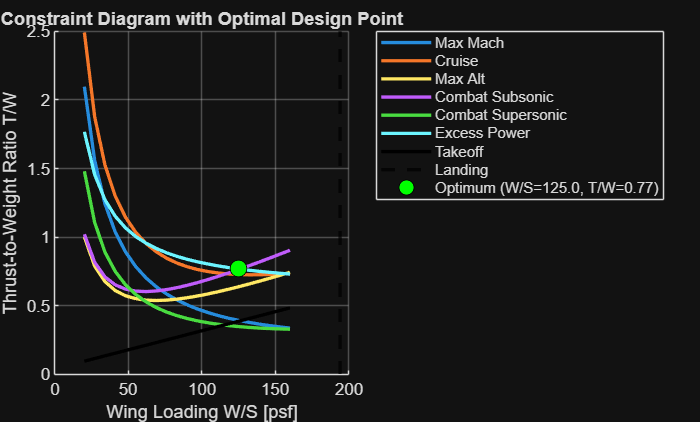


constraint_obj.plotConstraintDiagram(W_S, TW_table, T_Wto_takeoff, Wto_S_Landing, constraint_obj.optimal_WS, constraint_obj.min_TW, {constraints_table.Row{:}})

## Requirements

requirements_obj = Requirements(design);

## Run the project sizing class

% OLD COMMENT IGNORE THIS
% This calls the F16SizingLevel1 method directly. The method returns the
% converged W_TO. In the current class definition, results_table is assigned
% inside the method, but the class itself does not inherit handle, so the table
% may not persist outside the method depending on your inheritance tree.
% OLD COMMENT IGNORE THIS

% INITIALIZE THE SIZING OBJECT
sizing_obj       = F16SizingLevel1();


tol = 1e-3;
max_iteration = 40;
results = [];

LD_max = aero_obj.LD_max;
W_fixed = weight_obj.W_fixed;

W_S = constraint_obj.optimal_WS;
T_W = constraint_obj.min_TW;

W_TO = weight_obj.W_TO_guess;
S_ref = geometry_obj.mainwings.S_ref;

mission_data = mission_obj.missiondata;

for iteration = 1:max_iteration

     [weight_obj.total_fuel_used, weight_obj.fuel_fraction] = mission_obj.get_mission_fuel(propulsion_obj, mission_data, W_TO, LD_max);
     weight_obj.OEW = weight_obj.get_OEW(design.type, W_TO);
     weight_obj.OEW_frac = weight_obj.OEW/W_TO;

     W_TO_new = sizing_obj.compute_TOGW(weight_obj.OEW, weight_obj.total_fuel_used, W_fixed);
     difference = W_TO_new - W_TO;
     percent_diff = 100 * difference/W_TO;

     results(end+1, :) = [W_TO, W_fixed, weight_obj.fuel_fraction, weight_obj.OEW_frac, weight_obj.OEW, W_TO_new, difference, percent_diff, S_ref];

     if abs(difference) < tol
          break;
     end
     W_TO = W_TO_new;
     % T0 = T_W*W_TO;
     % S_ref = W_TO/W_S;

end
weight_obj.W_TO = W_TO;
sizing_obj.results_table = array2table(results, 'VariableNames', {'WTO', 'W_fixed', 'Fuel_fraction', 'Empty_weight_fraction', 'Empty_weight', 'WTO_new', 'Difference', 'Percent_Diff', 'S_ref'});
W_TO_final = W_TO_new;
sizing_output = sizing_obj.results_table;
disp(sizing_output);

     WTO     W_fixed    Fuel_fraction    Empty_weight_fraction    Empty_weight    WTO_new    Difference    Percent_Diff    S_ref
    _____    _______    _____________    _____________________    ____________    _______    __________    ____________    _____
    45000     5100         0.25039              0.58116              26152         41882       -3117.9         -6.9286      300 
    41882     5100         0.24985              0.58661              24569         39541       -2341.4         -5.5904      300 
    39541     5100          0.2494              0.59102              23369         37772       -1768.4         -4.4722      300 
    37772     5100         0.24901              0

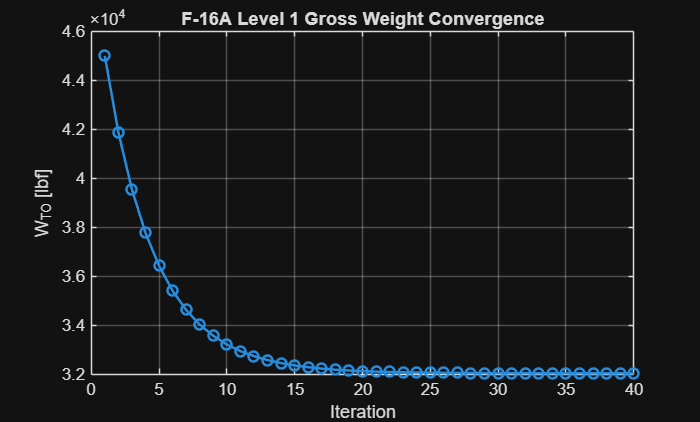


% propulsion_obj.T0 = T0;

figure('Name', 'Level 1 Gross Weight Convergence');
plot(1:height(sizing_obj.results_table.WTO), sizing_obj.results_table.WTO, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 1 Gross Weight Convergence');

## Plot closure error

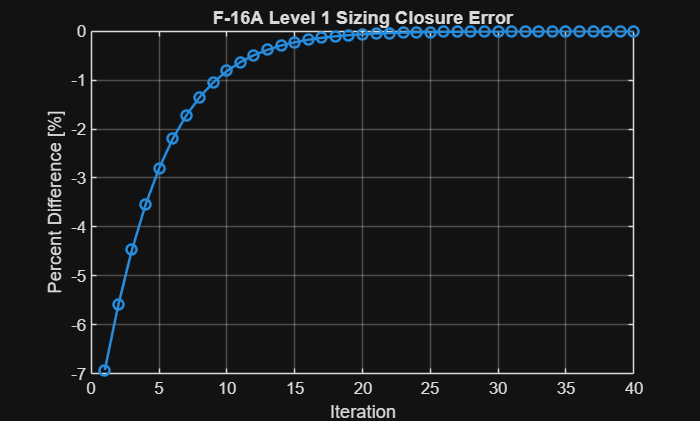

figure('Name', 'Level 1 Closure Error');
plot(1:height(sizing_obj.results_table.WTO), sizing_obj.results_table.Percent_Diff, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 1 Sizing Closure Error');

## Plot final weight breakdown

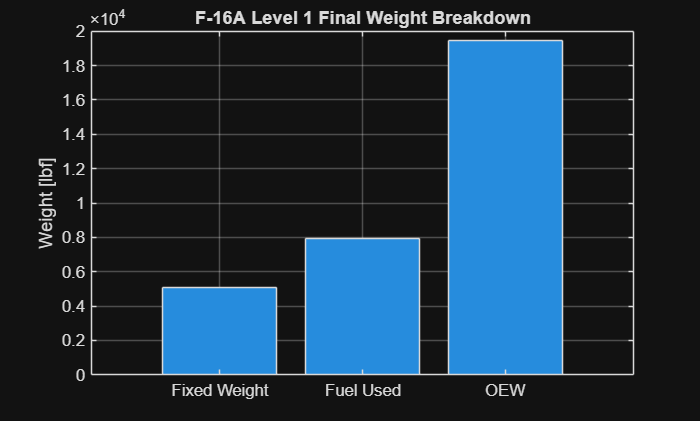

weightBreakdown = table( ...
     categorical(["OEW"; "Fuel Used"; "Fixed Weight"]), ...
     [sizing_output.Empty_weight(length(sizing_output.WTO)); ...
     sizing_output.Fuel_fraction(length(sizing_output.WTO)).*sizing_output.WTO(length(sizing_output.WTO)); ...
     sizing_output.W_fixed(length(sizing_output.WTO))], ...
     'VariableNames', {'Component', 'Weight_lbf'});

figure('Name', 'Level 1 Final Weight Breakdown');
bar(weightBreakdown.Component, weightBreakdown.Weight_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 1 Final Weight Breakdown');

## Save results into the AircraftDesign object

% % AircraftDesign is a handle class, so these assignments persist on the design
% % object during this MATLAB session.
%
design.WeightResults.Level1SizingTable = sizing_output;
design.WeightResults.W_TO              = sizing_output.WTO(length(sizing_output.WTO));
design.WeightResults.OEW               = sizing_output.Empty_weight(length(sizing_output.WTO));
design.WeightResults.FuelUsed          = sizing_output.Fuel_fraction(length(sizing_output.WTO)).*sizing_output.WTO(length(sizing_output.WTO));

design.AeroResults.Level1.LDmax         = aero_obj.LD_max;
design.AeroResults.Level1.AR_wetted     = aero_obj.AR_wet;
design.AeroResults.Level1.S_wet         = geometry_obj.design.S_wet;

% design.PropulsionResults.Level1.T0      = propulsion_obj.T0;
design.PropulsionResults.Level1.TSFC    = propulsion_obj.TSFC;